clearvars;
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
% location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\PIM06092023_sen3rotateleft90\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             location = [location
%                 [x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint
% end

% writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06092023_rotateaverages.txt');
% writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06092023_rotatelocations.txt')

location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06092023_rotatelocations.txt');
dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06092023_rotateaverages.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.028674     0.042354    -0.022934
    -0.028186     0.042214    -0.022748
    -0.027843     0.041836    -0.022487
    -0.027468     0.041977    -0.022413
    -0.026902     0.042194    -0.022247
    -0.025848     0.042457    -0.022094
    -0.025144     0.042642     -0.02188
    -0.024576     0.042805    -0.021843
     -0.02396     0.042917    -0.021802
    -0.023513     0.043017    -0.021659


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =     -0.013206     0.023246   -0.0063132
    -0.013039     0.022975   -0.0061222
    -0.013052     0.022525   -0.0058626
    -0.013189     0.022882   -0.0058174
    -0.013369      0.02302   -0.0056511
    -0.013597     0.023502   -0.0054608
    -0.013801     0.023853   -0.0053156
    -0.013964     0.023988   -0.0051903
    -0.014089     0.024242   -0.0050628
    -0.014253     0.024647   -0.0049565


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =     -0.030651     0.046224       0.1253
    -0.031171      0.04518      0.12598
     -0.03183     0.044219      0.12667
    -0.032102     0.042958      0.12748
     -0.03243     0.041007      0.12851
    -0.032944     0.037771      0.13015
    -0.033222     0.035421      0.13124
    -0.033482     0.033476      0.13217
    -0.033708     0.031439      0.13286
    -0.033817     0.029882      0.13356


sen4 = dataavg(:,10:12) %top right sensor

sen4 =     -0.041682    0.0023211    -0.020113
    -0.041657    0.0019472    -0.019783
    -0.041898     0.001363    -0.019527
    -0.042266    0.0012811    -0.019222
    -0.042802    0.0011163    -0.018817
    -0.043634   0.00086357    -0.018118
    -0.044313   0.00073424    -0.017639
    -0.044839   0.00051096    -0.017184
    -0.045311   0.00039142    -0.016746
    -0.045788   0.00017768    -0.016421


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


testB = 2*sen3

testB =     -0.061302     0.092448      0.25059
    -0.062343     0.090359      0.25196
    -0.063661     0.088438      0.25334
    -0.064205     0.085915      0.25496
     -0.06486     0.082015      0.25702
    -0.065888     0.075543      0.26031
    -0.066445     0.070841      0.26248
    -0.066964     0.066952      0.26434
    -0.067416     0.062878      0.26572
    -0.067634     0.059764      0.26712


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen3;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =     -0.033476     -0.71243      0.70094


fval =        21.555


fval/datasize

ans =     0.0044434


sqrt(sum(angle.^2))

ans =             1


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
ind = 10;
d_data = testB;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =     -0.011326     -0.24104      0.97045


fval =        26.001


fval/datasize

ans =     0.0053599


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =       0.04738     0.074859      0.20609
     0.043181     0.075461      0.20851
      0.03886     0.076006      0.21072
      0.03443     0.076493      0.21269
     0.029901      0.07692      0.21443
     0.025287     0.077285      0.21592
     0.020599     0.077588      0.21717
     0.015853     0.077826      0.21815
      0.01106     0.077999      0.21887
    0.0062365     0.078107      0.21933


expectB

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


fabdiff = expectB - faB

fabdiff =     0.0018766    -0.025603     0.019085
    0.0015658    -0.025743     0.019221
     0.001249    -0.025869     0.019338
   0.00092695    -0.025983     0.019435
   0.00060052    -0.026084     0.019513
   0.00027068     -0.02617      0.01957
  -6.1626e-05    -0.026243     0.019606
  -0.00039542    -0.026302     0.019621
  -0.00072971    -0.026346     0.019616
   -0.0010635    -0.026376     0.019589


max(fabdiff)

ans =     0.0042027    -0.025603     0.033794


%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =       0.04738     0.074859      0.20609
     0.043181     0.075461      0.20851
      0.03886     0.076006      0.21072
      0.03443     0.076493      0.21269
     0.029901      0.07692      0.21443
     0.025287     0.077285      0.21592
     0.020599     0.077588      0.21717
     0.015853     0.077826      0.21815
      0.01106     0.077999      0.21887
    0.0062365     0.078107      0.21933


fixapreds

fixapreds =       -6.6103       5.9897       41.124
      -6.6867       5.7445       41.128
      -6.7867       5.5125       41.114
      -6.8091       5.2264       41.132
      -6.8375       4.8019       41.173
      -6.9055       4.1025       41.224
       -6.935       3.6034        41.26
      -6.9602       3.1928        41.28
      -6.9903        2.775       41.314
      -6.9886       2.4481       41.325


fixafvalues

fixafvalues =    5.2861e-09
   1.7452e-09
   4.9753e-10
   1.5281e-09
   7.1101e-09
   5.7566e-10
    4.634e-12
   1.1823e-09
   1.3222e-09
   1.0292e-09


fixadiff = fixapreds - loc

fixadiff =       -1.6103        10.99       6.1245
      -2.1867       10.744       6.1282
      -2.7867       10.513        6.114
      -3.3091       10.226        6.132
      -3.8375       9.8019       6.1729
      -4.4055       9.1025       6.2238
       -4.935       8.6034       6.2604
      -5.4602       8.1928       6.2798
      -5.9903        7.775       6.3143
      -6.4886       7.4481        6.325


max(fixadiff)

ans =        12.613       12.415       7.9869


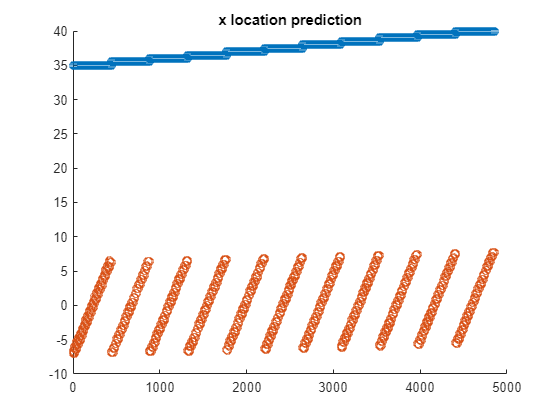

%predicted location using fixed angle
scatter(1:4851,fixapreds(:,1)) %x values
hold on
title('x location prediction')
hold off

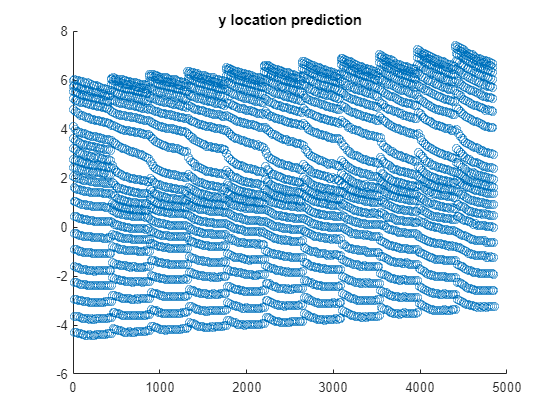

scatter(1:4851,fixapreds(:,2)) %y values
hold on
title('y location prediction')
hold off

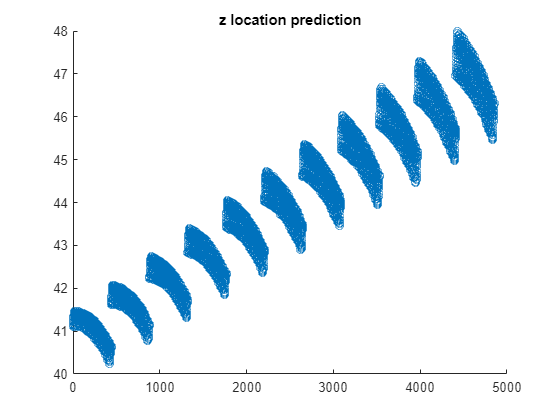

scatter(1:4851,fixapreds(:,3)) %z values
hold on
title('z location prediction')
hold off

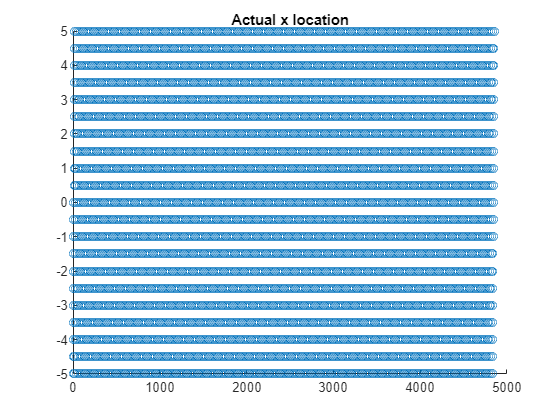

% scatter(1:4851,fixadiff(:,1))
% scatter(1:4851,fixadiff(:,2))
% scatter(1:4851,fixadiff(:,3))

%actual location of measurement
scatter(1:4851,loc(:,1))
hold on
title('Actual x location')
hold off

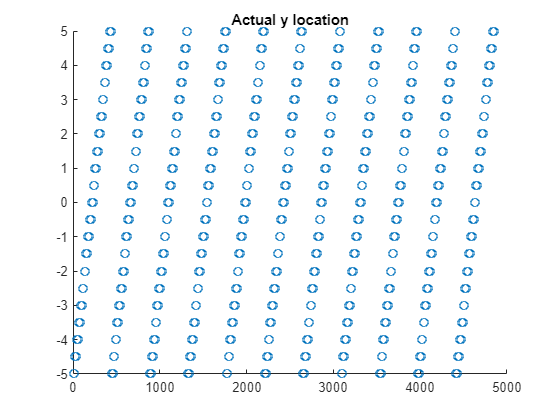

scatter(1:4851,loc(:,2))
hold on
title('Actual y location')
hold off

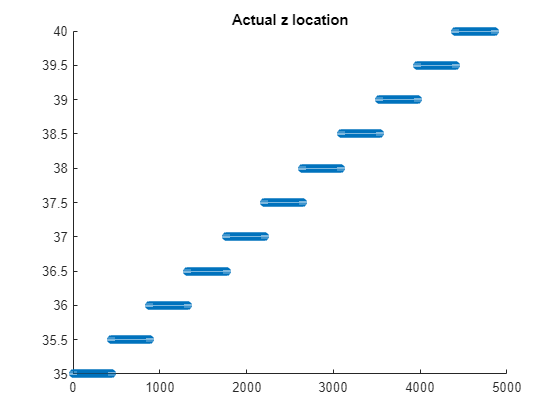

scatter(1:4851,loc(:,3))
hold on
title('Actual z location')
hold off

sqrt(441)

ans =     21


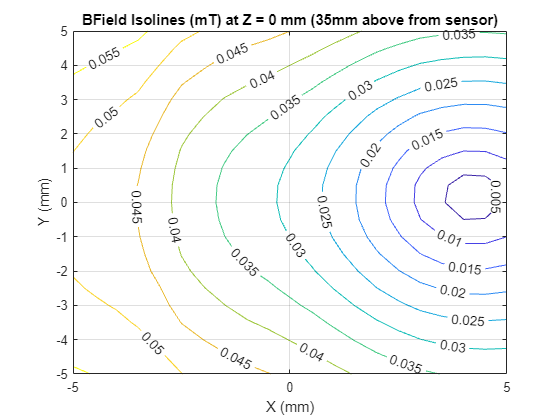

locavg = [location sen3];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

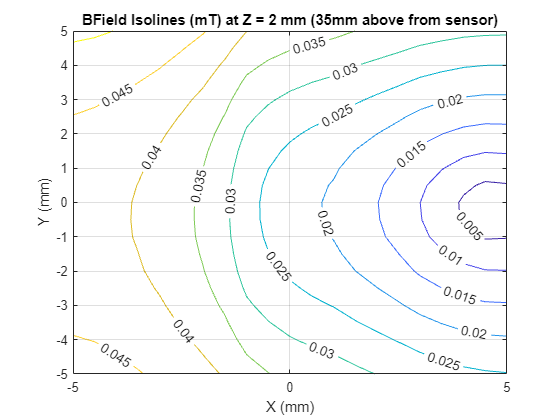

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 2 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

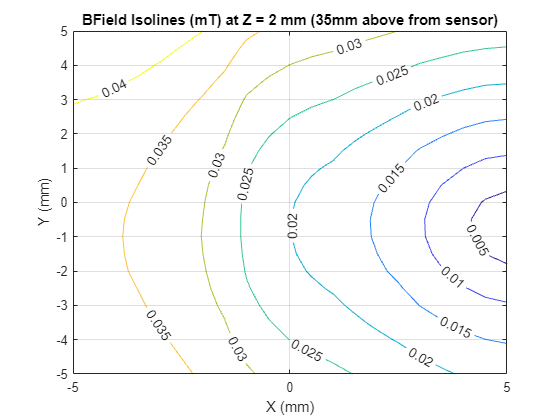

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:4851,locpred(:,1)) %x values
% hold on
% title('x location prediction')
% hold off
% scatter(1:4851,locpred(:,2)) %y values
% hold on
% title('y location prediction')
% hold off
% scatter(1:4851,locpred(:,3)) %z values
% hold on
% title('z location prediction')
% hold off
% % scatter(1:4851,fixadiff(:,1))
% % scatter(1:4851,fixadiff(:,2))
% % scatter(1:4851,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:4851,loc(:,1))
% hold on
% title('Actual x location')
% hold off
% scatter(1:4851,loc(:,2))
% hold on
% title('Actual y location')
% hold off
% scatter(1:4851,loc(:,3))
% hold on
% title('Actual z location')
% hold off

% scatter(1:4851, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end
